Reference:

Static, Vibration Analysis and Sensitivity Analysis of Stepped Beams Using Singularity Functions 

by Peng Cheng, Carla Davila and Gene Hou

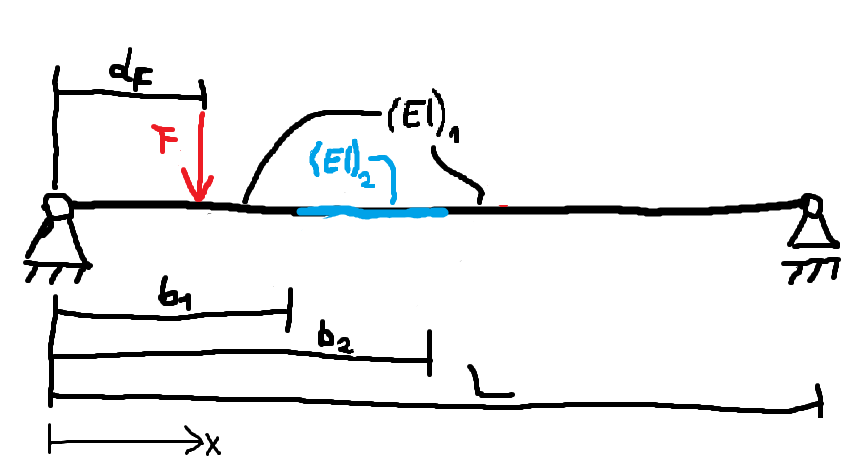

function [w,dw,ddw,M] = simpleSupportedBeam(x_val, E_val, L_val, dF_val, F_val, I_val, b_val,bc_left,bc_right)

**Input**

x_val .. value for beam position in m

E_val .. value for elastic modulus in N/m^2

L_val .. value for beam length in m

d_F_val .. value for load position in m

F_val .. value for load in N

I_val=[I_1 I_2] .. value for second moment of area in m^4

b_val=[b_1 b_2] .. values for region of inhomogeneity in m

bc_left .. boundary condition left side ('pinned' or 'fixed'); default value is 'pinned'

bc_right .. boundary condition left side ('pinned' or 'fixed'); default value is 'pinned'

**Output**

w .. displacement

dw .. first derivative of displacement (rotation)

ddw .. second derivative of displacement (curvature)

M .. bending moment

**Assumptions:**

$0 \leq L$, $0\leq E$, $0 \leq I_1$, $0 \leq I_2$

$0 \leq x \leq L
$,  $0 \leq d_F \leq L
$


$$0 \leq b_1 < b_2 \leq L
$$


if ~exist('bc_left','var') || isempty(bc_left)
    bc_left='pinned';
end
if ~exist('bc_right','var') || isempty(bc_right)
    bc_right='pinned';
end

syms M x E L dF F
syms(sym('C_',[1 4])) % integration constants
syms(sym('R_',[1 2])) % support reaction
syms(sym('b_',[1 2])) % position of irregularity
syms(sym('I_',[1 2])) % second moment of area

sf_0(x) =   heaviside(x); % singularity function: step function
sf_1(x) = x*heaviside(x); % singularity function: integration of step function

support reaction

R_1_sub=(F*(L-dF))/L;
R_2_sub=(F*dF)/L;

Bending moment

M(x) = R_1*sf_1(x) - F*sf_1(x-dF) + R_2*sf_1(x-L) +C_1*x +C_2;

Reciprocal of moment of inertia 1/I(x)

invI(x) = 1/I_1 - (1/I_1-1/I_2)*sf_0(x-b_1) - (1/I_2-1/I_1)*sf_0(x-b_2);

Differential eq.

ddw(x)=M(x)*invI(x)/E;
ddw(x)=expand(ddw);
 dw(x)=int(ddw(x),x) + C_3;
  w(x)=int( dw(x),x) + C_4;

Boundary conditions

if strcmp(bc_left,'pinned')
    bc1= w(0)==0;
    bc2= M(0)==0;
elseif strcmp(bc_left,'fixed')
    bc1=  w(0)==0;
    bc2= dw(0)==0;
else
    error('Unknown boundary condition.')
end
if strcmp(bc_right,'pinned')
    bc3= w(L)==0;
    bc4= M(L)==0;
elseif strcmp(bc_right,'fixed')
    bc3=  w(L)==0;
    bc4= dw(L)==0;
else
    error('Unknown boundary condition.')
end

bc=[bc1 bc2 bc3 bc4];

zeroTerms=[heaviside(x-L) heaviside(dF-L) ...
          heaviside(-b_1) heaviside(-b_2) heaviside(-L) heaviside(-dF)  ...
          ];
bc=subs(bc,zeroTerms,zeros(size(zeroTerms)));

oneTerms=[heaviside(L) heaviside(L-x) heaviside(L-dF) ...
           sign(L-b_1) sign(L-b_2) sign(L) sign(b_1) sign(b_2) ...
           heaviside(b_1) heaviside(b_2) heaviside(x)];
bc=subs(bc,oneTerms,ones(size(oneTerms)));

Solve the diff. eq.

sol=solve(bc,[C_1 C_2 C_3 C_4]);

Substitute constants

ddw(x)=subs(ddw(x),sym('C_',[1 4]),struct2array(sol));
 dw(x)=subs( dw(x),sym('C_',[1 4]),struct2array(sol)); 
  w(x)=subs(  w(x),sym('C_',[1 4]),struct2array(sol));
  M(x)=subs(  M(x),sym('C_',[1 4]),struct2array(sol));

Substitute bearing reactions

ddw_val(x)=subs(ddw(x),sym('R_',[1 2]),[R_1_sub R_2_sub]);  
 dw_val(x)=subs( dw(x),sym('R_',[1 2]),[R_1_sub R_2_sub]);
  w_val(x)=subs(  w(x),sym('R_',[1 2]),[R_1_sub R_2_sub]);
  M_val(x)=subs(  M(x),sym('R_',[1 2]),[R_1_sub R_2_sub]);

Substitution of variables with values

vars=[F     dF       I_1      I_2      b_1      b_2      L     E];
vals=[F_val dF_val I_val(1) I_val(2) b_val(1) b_val(2) L_val E_val];

ddw(x)=subs(ddw_val(x),vars,vals);
 dw(x)=subs(dw_val(x),vars,vals);
  w(x)=subs(w_val(x),vars,vals);
  M(x)=subs(M_val(x),vars,vals);

ddw=subs(ddw(x),x,x_val);
 dw=subs( dw(x),x,x_val);
  w=subs(  w(x),x,x_val);
  M=subs(  M(x),x,x_val);

end